# SISTEMAS DE CONTROL II

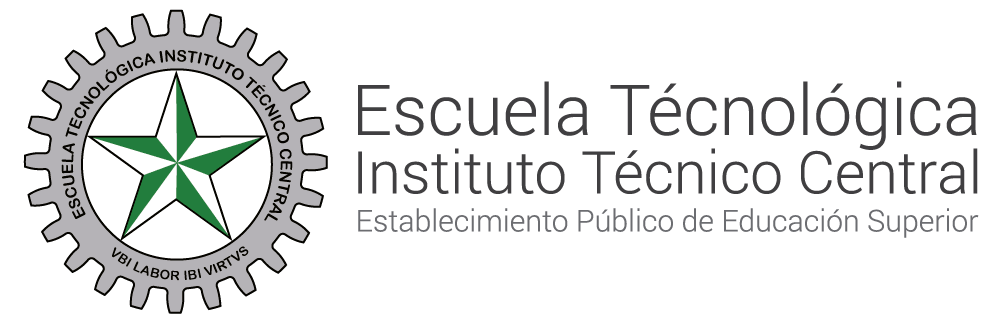

# **Transformada Z**

**Autor ** **ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c**

**Coautores:  Leidy Helena Herran Briceño, Brayan Camilo Guauta Arevalo**

## ¿Que es la transformada z ?

El metodo de la transformada Z es un metodo operacional que se utiliza para trabajar con sistemas en tiempo discreto 

La **transformada Z** se define:


$$Y\left(z\right)=Z\left\lbrack y\left(t\right)\right\rbrack =Z\left\lbrack y\left(\textrm{kT}\right)\right\rbrack =\sum_{k=0}^{\infty } y\left(\textrm{kT}\right)z^{-k}$$


Donde: 

$T:$ Es el periodo de muestreo

$y\left\lbrack k\right\rbrack :$ representa los valores de la señal discreta en instantes $k$. 

$k:$ son todos los valores de cero (0) o numeros enteros positivos 0,1,2.....($\infty$)  

Para el escalón unitario discreto se tiene **que **$u\left(k\right)=1\;\textrm{para}\;k\ge 0$**:**

## RESOLVER $y\left\lbrack k\right\rbrack =1-e^{-\textrm{akT}}$

La funcion en terminos de transformada z se define:


$$Y\left(z\right)=\sum_{k=0}^{\infty } \left\lbrack 1-e^{-\textrm{akT}} \right\rbrack \cdot z^{-k}$$


Usando la **propiedad básica de la transformada Z**: "**linealidad";** la cual permite combinar las transformadas Z de dos señales de manera lineal, es decir, sumarlas o restarlas directament, se obtiene:


$$Y\left(z\right)=a\cdot \textrm{y1}\left\lbrack k\right\rbrack \pm b\cdot \textrm{y2}\left\lbrack k\right\rbrack =\textrm{Y1}\left(z\right)\pm \textrm{Y2}\left(z\right)$$



$$Y\left(z\right)=\sum_{k=0}^{\infty } 1\cdot z^{-k} -\sum_{k=0}^{\infty } e^{-\textrm{akT}} \cdot z^{-k}$$


### PASO 1

### Resolver para $Y\left(z\right)=\sum_{k=0}^{\infty } 1\cdot z^{-k}$

Para resolver Z, se usara la serie geométrica.

Una **serie geométrica** es una suma de términos en la que cada término se obtiene multiplicando el término anterior por una constante llamada **razón** (r). La forma general de una serie geométrica es:


$$\sum_{n=0}^N r^k =\frac{r^{N+1} -1}{r-1}$$
  

Se define: 

- 
$${{1\cdot z}^{-k} =\left\lbrack \frac{1}{z}\right\rbrack }^k$$
 

- $\left(r\right)=\frac{1}{z}$, cambio de variable

$Y\left(z\right)=\sum_{n=0}^N r^k =\frac{r^{N+1} -1}{r-1}=\;\frac{{\frac{1}{z}}^{\infty +1} -1}{\frac{1}{z}-1}\;$, cuando $\frac{1}{z}$ tiende a infinito el limite es cero (0), el resultado converge hacia $0$ $\lim_{n\longrightarrow \infty } {\left(\frac{1}{z}\right)}^n =0,\textrm{si}\;\left|\frac{1}{z}\right|<1$

$Y\left(z\right)=\frac{-1}{\frac{1}{z}-1}\cdot \frac{-z}{-z}=\frac{z}{z-1}$, se obtiene la transformada del escalon unitario $u\left(k\right)=\frac{\mathit{\mathbf{z}}}{\mathit{\mathbf{z}}-1}$

syms z n 
assume(abs(z) > 1);

r = 1/z; 
serie_geometrica = symsum(r^n, n, 0, Inf); 

formula_serie_geometrica = -1 / (r - 1)

$$formula\_serie\_geometrica = -\frac{1}{\frac{1}{z}-1}$$

Y = simplify(formula_serie_geometrica)

$$Y = \frac{z}{z-1}$$

#### GRAFICA PARA LA PRIMERA TRANSFORMADA Z $y\left\lbrack k\right\rbrack =1$

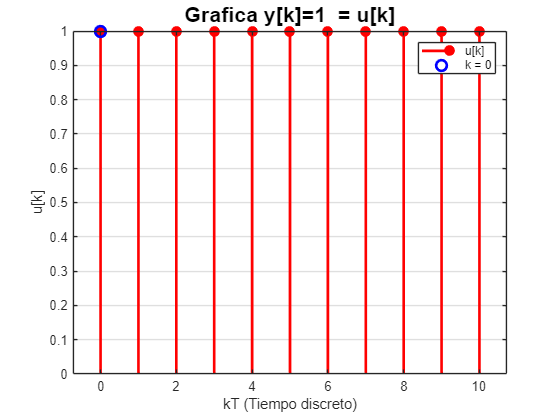

k = 0:10; 
u = ones(size(k)); 
figure;  
stem(k, u, 'filled', 'LineWidth', 2.0, 'Color', 'r'); 
title('Grafica y[k]=1  = u[k]', 'FontSize', 16,'Color','k');
xlabel('kT (Tiempo discreto)'); 
ylabel('u[k]'); 
grid on;
hold on; 
plot(0, 1, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
legend('u[k]', 'k = 0');
hold off; 

### PASO 2

### 2. Resolver para $Y\left(z\right)=e^{-\textrm{akT}}$

Para resolver Z, se usara la serie geométrica.

Una **serie geométrica** es una suma de términos en la que cada término se obtiene multiplicando el término anterior por una constante llamada **razón** (r). La forma general de una serie geométrica es:


$$\sum_{n=0}^N r^k =\frac{r^{N+1} -1}{r-1}$$
  

Se define: 

- 
$${{e^{-a,\mathrm{kT}} \cdot z}^{-k} =\left\lbrack e^{-\mathrm{aT}} \cdot z^{-1} \right\rbrack }^k$$
 

- $\left(r\right)=e^{-\mathrm{aT}} \cdot z^{-1}$, cambio de variable

$Y\left(z\right)=\sum_{n=0}^N r^k =\frac{r^{N+1} -1}{r-1}=\;\frac{{e^{-\mathrm{aT}} \cdot z^{-1} }^{\infty +1} -1}{e^{-\mathrm{aT}} \cdot z^{-1} -1}\;$, cuando $e^{-\textrm{aT}} \cdot z^{-1}$ tiende a infinito el limite es cero (0),  el resultado converge hacia $0$ $\lim_{n\longrightarrow \infty } {\left(\frac{1}{z}\right)}^n =0,\textrm{si}\;\left|\frac{1}{z}\right|<1$

$Y\left(z\right)=\frac{-1}{e^{-\mathrm{aT}} \cdot \frac{1}{z}-1}\cdot \frac{-z}{-z}=\frac{z}{z-e^{-\mathrm{aT}} }$, se obtiene la transformada exponencial $Y\left(z\right)=\frac{\mathit{\mathbf{z}}}{z-e^{-\textrm{aT}} }$

syms z k a T; 
assume(abs(z) > exp(-a*T));
r= exp(-a*T) * z^(-1)

$$r = \frac{{\mathrm{e}}^{-T\,a}}{z}$$

formula_serie_geometrica_exp = -1 / (r - 1)

$$formula\_serie\_geometrica\_exp = -\frac{1}{\frac{{\mathrm{e}}^{-T\,a}}{z}-1}$$

#### GRAFICA PARA LA SEGUNDA TRANSFORMADA Z $y\left\lbrack k\right\rbrack =e^{-\textrm{akT}}$

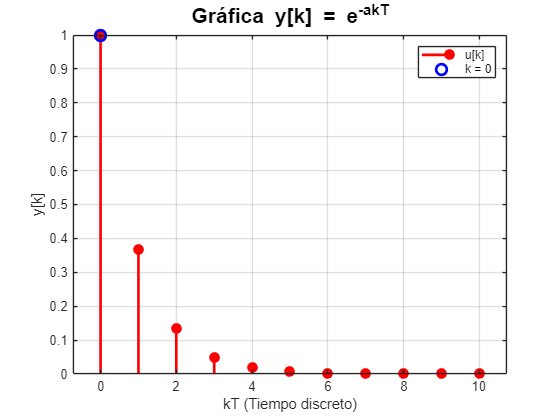

% Parámetros
a = 1; % Constante
T = 1; % Período de muestreo
k = 0:10; % Vector de tiempo discreto
% Calcular la secuencia exponencial
y = exp(-a*k*T);
% Graficar la secuencia exponencial
figure;
stem(k, y, 'filled', 'LineWidth', 2.0, 'Color', 'r'); % Representación de datos discretos
title('Gráfica y[k] = e^{-akT}', 'FontSize', 16, 'Color', 'k'); % Título
xlabel('kT (Tiempo discreto)'); % Etiqueta en x
ylabel('y[k]'); % Etiqueta en y
grid on; % Activar cuadrícula
hold on; % Conservar la gráfica actual al añadir otr
plot(0, 1, 'bo', 'MarkerSize', 8, 'LineWidth', 2); % Marcar el punto n = 0
legend('u[k]', 'k = 0');
hold off; % activa o desactiva el estado de permanencia, aqui borra o desactiva

### PASO 3

### 3. Unificar y resolver para $Y\left(z\right)={1-e}^{-\textrm{akT}}$


$$Y\left(z\right)=a\cdot \textrm{y1}\left\lbrack k\right\rbrack \pm b\cdot \textrm{y2}\left\lbrack k\right\rbrack =\textrm{Y1}\left(z\right)\pm \textrm{Y2}\left(z\right)$$


$Y\left(z\right)=\frac{z}{z-1}-\frac{z}{z-e^{-\textrm{akT}} }$, se multiplica para simplificar

 
$$Y\left(z\right)=\frac{z\left(z-e^{-\textrm{akT}} \right)-z\left(z-1\right)}{\left(z-1\right)\left(z-e^{-\textrm{akT}} \right)}=\frac{z^2 -ze^{-\textrm{akT}} -z^2 +z}{\left(z-1\right)\left(z-e^{-\textrm{akT}} \right)}$$


$Y\left(z\right)=\frac{z-ze^{-\textrm{akT}} }{\left(z-1\right)\left(z-e^{-\textrm{akT}} \right)}$, como resutado se obtiene  $Y\left(z\right)=\frac{z\left(1-e^{-\textrm{akT}} \right)}{\left(z-1\right)\left(z-e^{-\textrm{akT}} \right)}$

syms a k T z 

f = 1 - exp(-a*k*T);

F_z = ztrans(f, k, z)

$$F\_z = \frac{z}{z-1}-\frac{z}{z-{\mathrm{e}}^{-T\,a}}$$

### GRAFICA PARA TRANSFORMADA Z $y\left\lbrack k\right\rbrack ={1-e}^{-\textrm{akT}}$ 

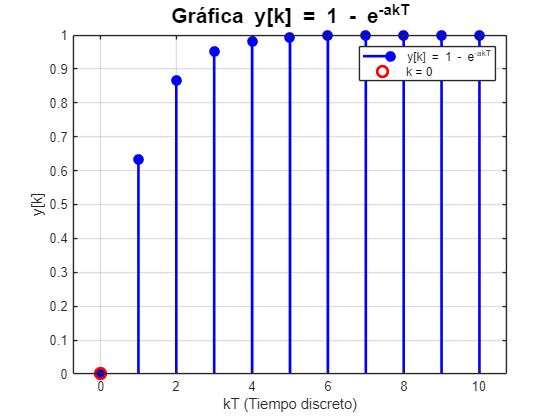

a = 1; 
T = 1; 
k = 0:10; 
y = 1 - exp(-a*k*T);
figure;
stem(k, y, 'filled', 'LineWidth', 2.0, 'Color', 'b'); 
title('Gráfica y[k] = 1 - e^{-akT}', 'FontSize', 16, 'Color', 'k'); 
xlabel('kT (Tiempo discreto)'); 
ylabel('y[k]'); 
grid on; 
hold on; 
plot(0, 0, 'ro', 'MarkerSize', 8, 'LineWidth', 2); 
legend('y[k] = 1 - e^{-akT}', 'k = 0'); 
hold off; 